## Opdrachten

### Oefening 1

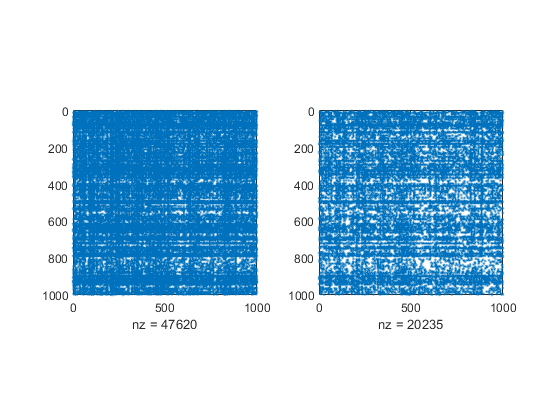

load('MovieLens_Subset.mat');
figure('Name','Sparsity plots');
subplot(1,2,1);
spy(R(1:1000,1:1000));
subplot(1,2,2);
spy(T(1:1000,1:1000));

### Oefening 2

**Voor de volle matrix R** vinden we het aantal matrixwaarden vermenigvuldigd met de 8 bytes voor hun vlottendekommavoorstelling: 2206*12488*8 bytes = 220 388 224 B

**Voor de spaarse matrix R** vinden we: 1157858*(2*4+8) bytes = 18 525 728 B, namelijk voor de 2 coordinaatgetallen en de bijhorende vlottendekommawaarde.

**Voor de lage-rang benadering** vinden we de som van de dimensies van R vermenigvuldigd met de rank en 8 bytes. R kan namelijk compact voorgesteld worden door R voor te stellen als het product van F en W. Waarbij F met dimensie [2206 r] en W dimensie [12488 r], bestaande uit dubbele-precisie vlottendekommawaarden. Dit geeft rank*117552 B.

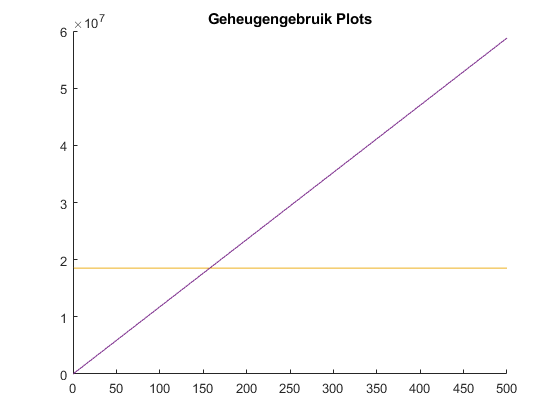

r = 0:1:500;
[m,n] = size(R);    % Dimensions of matrix R
y0 = 8*m*n;         % y0 = Memory req. for dense matrix
y1 = 16*nnz(R);     % y1 = Memory req. for sparse matrix
y2 = 8*r*(m+n);     % y2 = Memory req. for lower rank est.

figure;
title('Geheugengebruik Plots')
hold on
% plot(ones(500)*y0);
plot(ones(500)*y1);
plot(r,y2);
hold off

In de figuur wordt grafisch voorgesteld dat voor rank = 1157858/117552 = 158 de twee laatste functieverlopen snijden.

### Oefening 5

We gebruiken enkel de coordinaten van onze (niet-nul) spaarse-matrix elementen om de berekeningen door te voeren. Voor elk coordinatenpaar (i,j) vermenigvuldigen we de i'de rij van F met de j'de kolom van W. De uitkomsten van deze vermenigvuldigingen worden bijgehouden in een lijst en worden vervolgens gebruikt om de resulterende spaarse matrix op te stellen.

### Oefening 7

mu = r0629309_userMeans(R);
[muSorted,indices] = sort(mu);
lowestAVG= muSorted(1:3);
userIndices = indices(1:3);
lowAVG= horzcat(lowestAVG,userIndices)

lowAVG =          0.51          488
      0.57273        11381
      0.89835         4205


nmbHR = nnz(mu==5)

nmbHR =     13


Er zijn 13 gebruikers met een gemiddelde gelijk aan 5.

### Oefening 9

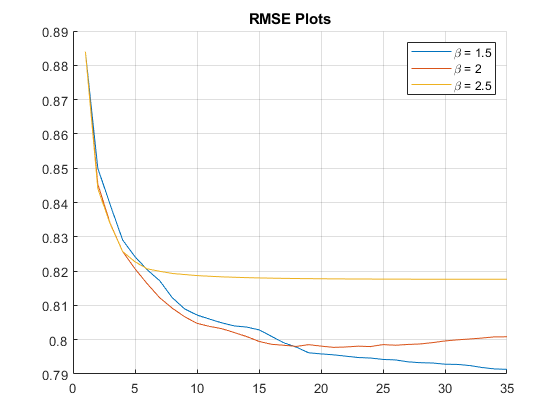

figure;
title('RMSE Plots')
for beta = [1.5 2 2.5]
    err = zeros(35,1);
    [F,W] = r0629309_constructModel(R,length(err),beta);
    for k = 1:length(err)
        err(k) = r0629309_RMSE(T, r0629309_sparseModel(F(:,1:k),W(:,1:k),T));
    end
    hold all; plot(err); drawnow;
end
legend('\beta = 1.5', '\beta = 2', '\beta = 2.5');
grid on;

### Oefening 10

[F20,W20] = r0629309_constructModel(R,20,2);
codeFragmentOutput = round(F(1987,:))

codeFragmentOutput =      1    -4     0    -3     3    -2     2    -1     1    -1     1    -1     1    -1     1    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


### Oefening 12

Sinds we enkel de gemiddeldes bijhouden en nooit de volledige matrix F*W' berekenen krijgen we een O(max(m,n)) geheugencomplexiteit. 

Elk element (i; j) berekenen we in-place door de i'de rij van F te vermenigvuldigen met de j'de kolom van W.

### Oefening 13

format short g
[ movieIDs, score] = r0629309_actualBestMovies(R);
movieRatings = horzcat(movieIDs,score,r0629309_countVotes(R)')

movieRatings =          2055       4.4806          506
         2075       4.3258         2620
         2193       4.2982          488
         2181       4.2595           82
         2132       4.2023          384
         1932       4.1995          410
         1972       4.1975          460
          816       4.1723          552
           78       4.1535          367
         2035       4.1467         5505



[ movieIDsPredicted, scorePredicted] = r0629309_predictedBestMovies(F20,W20);
predictedMovieRatings = horzcat(scorePredicted,movieIDsPredicted);

top25Actual = movieIDs(1:25);
top25Predicted =  movieIDsPredicted(1:25);

topMovieNames = cell(25,2);
for i = 1:1:25
    topMovieNames{i,1} = movieLabel{top25Actual(i)};
    topMovieNames{i,2} = movieLabel{top25Predicted(i)};
end

topMovieNames

topMovieNames = 25×2 cell array
    {'Planet Earth II (2016)'                              }    {'Inception (2010)'                    }
    {'Black Mirror: White Christmas (2014)'                }    {'Interstellar (2014)'                 }
    {'Won't You Be My Neighbor? (2018)'                    }    {'Whiplash (2014)'                     }
    {'Sherlock - A Study in Pink (2010)'                   }    {'Ex Machina (2015)'                   }
    {'Blue Planet II (2017)'                               }    {'Intouchables (2011)'                 }
    {'Over the Garden Wall (2013)'                         }    {'Django Unchained (2012)'             }
    {'Whiplash (2013)'                                     }    {'The Martian (2015)'                  }
    {'Human Planet (2011)'                                 }    {'Arrival (2016)'                      }
    {'Inception (2010)'                                    }    {'Gone Girl (2014)'                    }
    {'The Night Of (201

Links vinden we de eigenlijke topfilms, rechts de voorspelde. 

In de praktijk leunt het voorspelde vaak dichter aan bij de realiteit wegens de eerder beperkte aantal reviews. Indien we een kijkje nemen in de derde kolom dan kan men waarnemen dat het eigenlijke aantal review vaak kleiner is dan 1000. Met een responsgraad < 10% van de populatie is zo'n factuele voorspelling dus niet al te accuraat. In feite zijn, integenstelling tot de factuele lijst, de twee eerste voorspelde films zelfs echte kaskrakers gebleken!.

### Oefening 15 

**Recommendations for user 98**

[ movieIDs, score] = r0629309_predictedBestMoviesForUser(R,F20,W20,98);
movieRatingsForUser = horzcat(score,movieIDs);
top10 = movieIDs(1:10)';

favMoviePredictions = r0629309_getMovieNamesForIDs(top10)

favMoviePredictions = 10×1 cell array
    {'The Hunger Games (2012)'                          }
    {'Deadpool (2016)'                                  }
    {'Hobbit: An Unexpected Journey, The (2012)'        }
    {'The Martian (2015)'                               }
    {'The Hunger Games: Mockingjay - Part 1 (2014)'     }
    {'About Time (2013)'                                }
    {'Star Wars: Episode VII - The Force Awakens (2015)'}
    {'Frozen (2013)'                                    }
    {'Her (2013)'                                       }
    {'Iron Man 3 (2013)'                                }


[idT,colT,valT] = find(T);
ratings = valT(colT==98 & valT >= 4.5);
testIDs = idT(colT==98 & valT >= 4.5);

favMoviePredictions = r0629309_getMovieNamesForIDs(testIDs)

favMoviePredictions = 15×1 cell array
    {'How to Train Your Dragon (2010)'             }
    {'The Hunger Games (2012)'                     }
    {'Dark Knight Rises, The (2012)'               }
    {'Pitch Perfect (2012)'                        }
    {'Hobbit: An Unexpected Journey, The (2012)'   }
    {'Way, Way Back, The (2013)'                   }
    {'Short Term 12 (2013)'                        }
    {'Thor: The Dark World (2013)'                 }
    {'Wolf of Wall Street, The (2013)'             }
    {'How to Train Your Dragon 2 (2014)'           }
    {'The Hunger Games: Mockingjay - Part 1 (2014)'}
    {'Deadpool (2016)'                             }
    {'Guardians of the Galaxy 2 (2017)'            }
    {'Sherlock: The Abominable Bride (2016)'       }
    {'Kubo and the Two Strings (2016)'             }


**Recommendations for user 10100**

[ movieIDs, score] = r0629309_predictedBestMoviesForUser(R,F20,W20,10100);
movieRatingsForUser = horzcat(score,movieIDs);
top10 = movieIDs(1:10)';

favMoviePredictions = r0629309_getMovieNamesForIDs(top10)

favMoviePredictions = 10×1 cell array
    {'Guardians of the Galaxy (2014)'            }
    {'Deadpool (2016)'                           }
    {'Captain America: The Winter Soldier (2014)'}
    {'Interstellar (2014)'                       }
    {'Intouchables (2011)'                       }
    {'Big Hero 6 (2014)'                         }
    {'Arrival (2016)'                            }
    {'Logan (2017)'                              }
    {'Edge of Tomorrow (2014)'                   }
    {'Rise of the Planet of the Apes (2011)'     }


ratings = valT(colT==10100 & valT >= 4.5);
testIDs = idT(colT==10100 & valT >= 4.5);

favMoviePredictions = r0629309_getMovieNamesForIDs(testIDs)

favMoviePredictions = 19×1 cell array
    {'King's Speech, The (2010)'                  }
    {'Rise of the Planet of the Apes (2011)'      }
    {'Muppets, The (2011)'                        }
    {'Dark Knight Rises, The (2012)'              }
    {'Mission: Impossible - Ghost Protocol (2011)'}
    {'Hobbit: An Unexpected Journey, The (2012)'  }
    {'Misérables, Les (2012)'                     }
    {'Star Trek Into Darkness (2013)'             }
    {'World's End, The (2013)'                    }
    {'Thor: The Dark World (2013)'                }
    {'Hobbit: The Desolation of Smaug, The (2013)'}
    {'Interstellar (2014)'                        }
    {'Captain America: The Winter Soldier (2014)' }
    {'Guardians of the Galaxy (2014)'             }
    {'Big Hero 6 (2014)'                          }
    {'Deadpool (2016)'                            }
    {'Doctor Who: Last Christmas (2014)'          }
    {'Piper (2016)'                               }
    {'Baby Driver (2017)' 

### Oefening 17

movieIDs = [29;78;86;169;178;492;530;703;1136;1190;1287;1364;1381;1388;1443;1466;1602;1709;1848;1931];
score = [2.5;5;2.2;3.5;4.2;4.8;4;4;5;5;4.8;4.2;5;5;4;3;2;4;4;5];
nW = r0629309_addUser(F20,W20,movieIDs,score);

[ movieIDs, score] = r0629309_predictedBestMoviesForUser(R,F20,nW,12489);
movieRatingsForUser = horzcat(score,movieIDs);
top10 = movieIDs(1:10)';
favMoviePredictions = r0629309_getMovieNamesForIDs(top10)

favMoviePredictions = 10×1 cell array
    {'Edge of Tomorrow (2014)'       }
    {'Looper (2012)'                 }
    {'John Wick (2014)'              }
    {'Cabin in the Woods, The (2012)'}
    {'The Hunger Games (2012)'       }
    {'Snowpiercer (2013)'            }
    {'Pacific Rim (2013)'            }
    {'Gone Girl (2014)'              }
    {'Prometheus (2012)'             }
    {'Arrival (2016)'                }


De resultaten stemmen goed overeen met mijn favorieten, namelijk Science Fiction films. Enkel 'The Cabin in the Woods' valt uit de boot aangezien ik geen fan ben van het 'Horror'-concept.

### Oefening 20 

In de onderstaande output ziet men dat de correlaties, op het voorlaatste voorbeeld na, realistisch zijn. Men kan nagaan dat dit klopt op de gegeven movie-recommendation-systemen. Bij Moneyball zijn er enkele films gerelateerd waarbij het concept actie, ipv. het concept drama overheerst.

*De categorieën van elke cluster staan boven de console-output. *

n = [15;15;15;10;10];
k = [77;178;346;398;312];
str = ["Animation Movies","History, Thriller","Marvel, Superheroes","History, Drama, Action","Young-Adult, Comedy"];
C = r0629309_correlationMatrix(F20,W20);
for i = 1:1:5
    display(str(i));
    mIDs = r0629309_similarMovies(C,k(i),n(i));
    correlatedMovies = r0629309_getMovieNamesForIDs(mIDs)
    fprintf('\n');
end

    "Animation Movies"



correlatedMovies = 15×1 cell array
    {'Despicable Me (2010)'             }
    {'Despicable Me 2 (2013)'           }
    {'Tangled (2010)'                   }
    {'Megamind (2010)'                  }
    {'How to Train Your Dragon 2 (2014)'}
    {'Frozen (2013)'                    }
    {'Big Hero 6 (2014)'                }
    {'Brave (2012)'                     }
    {'Monsters University (2013)'       }
    {'How to Train Your Dragon (2010)'  }
    {'Wreck-It Ralph (2012)'            }
    {'Kung Fu Panda 2 (2011)'           }
    {'Zootopia (2016)'                  }
    {'Finding Dory (2016)'              }
    {'Hotel Transylvania (2012)'        }


    "History, Thriller"



correlatedMovies = 15×1 cell array
    {'King's Speech, The (2010)'      }
    {'Argo (2012)'                    }
    {'Intouchables (2011)'            }
    {'The Imitation Game (2014)'      }
    {'The Theory of Everything (2014)'}
    {'Help, The (2011)'               }
    {'Moneyball (2011)'               }
    {'Spotlight (2015)'               }
    {'Hidden Figures (2016)'          }
    {'Bridge of Spies (2015)'         }
    {'True Grit (2010)'               }
    {'Captain Phillips (2013)'        }
    {'Rush (2013)'                    }
    {'Midnight in Paris (2011)'       }
    {'Life of Pi (2012)'              }


    "Marvel, Superheroes"



correlatedMovies = 15×1 cell array
    {'Captain America: The First Avenger (2011)'  }
    {'Avengers: Age of Ultron (2015)'             }
    {'Captain America: The Winter Soldier (2014)' }
    {'Iron Man 3 (2013)'                          }
    {'Captain America: Civil War (2016)'          }
    {'Ant-Man (2015)'                             }
    {'Thor (2011)'                                }
    {'Thor: The Dark World (2013)'                }
    {'Iron Man 2 (2010)'                          }
    {'Doctor Strange (2016)'                      }
    {'Amazing Spider-Man, The (2012)'             }
    {'X-Men: Apocalypse (2016)'                   }
    {'Wolverine, The (2013)'                      }
    {'Wonder Woman (2017)'                        }
    {'Mission: Impossible - Ghost Protocol (2011)'}


    "History, Drama, Action"



correlatedMovies = 10×1 cell array
    {'Moneyball (2011)'       }
    {'Town, The (2010)'       }
    {'Captain Phillips (2013)'}
    {'Rush (2013)'            }
    {'Zero Dark Thirty (2012)'}
    {'Fighter, The (2010)'    }
    {'Big Short, The (2015)'  }
    {'Argo (2012)'            }
    {'50/50 (2011)'           }
    {'Warrior (2011)'         }


    "Young-Adult, Comedy"



correlatedMovies = 10×1 cell array
    {'Hangover Part II, The (2011)' }
    {'Dictator, The (2012)'         }
    {'Hangover Part III, The (2013)'}
    {'Friends with Benefits (2011)' }
    {'The Interview (2014)'         }
    {'Due Date (2010)'              }
    {'Horrible Bosses (2011)'       }
    {'Hot Tub Time Machine (2010)'  }
    {'Bad Teacher (2011)'           }
    {'No Strings Attached (2011)'   }


## Hulpfuncties

### sparseModel

### userMeans

### RMSE

### constructModel

### actualBestMovies

### predictBestMovies

### predictedBestMoviesForUser

### addUser

### correlationMatrix

### similarMovies